# ENGR105    ---    Problem Set 4    ---   Loops and Conditionals

## Due: Friday, 9/25/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW4.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu.

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Practice using for loops, while loops, and conditional statements.

- Continue to gain confidence creating custom functions.

- Compare the computational efficiency of `for` loops and vectorization.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (20 pts): `for` loops

Solve each of the following using `for`** loops**. You should have at least one `for` loop in each subpart.

**a) Vector.** Produce the following vector. After your code, display your vector using `disp()`.

        
$${\textrm{p1}}_- a=\left\lbrack \begin{array}{cccccccccc}
1 & 3 & 5 & 7 & 9 & 11 & 13 & 15 & 17 & 19
\end{array}\right\rbrack$$


i = 1;
p1_a = [];
for k = 1:10
    p1_a(k) = i;
   %input only odd numners into vector
    i = i+2;
end
disp(p1_a)

     1     3     5     7     9    11    13    15    17    19



**b) Infinite Sequence. **Produce the vector with the first **100 elements** of the following sequence. After your code, *display only the last element*. That is, run `disp(p1_b(100)).`

        
$$\begin{array}{l}
{\textrm{p1}}_- b\left(1\right)=0\\
{\textrm{p1}}_- b\left(2\right)=1\\
{\textrm{p1}}_- b\left(3\right)=3\\
{\textrm{p1}}_- b\left(4\right)={\textrm{p1}}_- b\left(3\right)+{\textrm{p1}}_- b\left(2\right)-{\textrm{p1}}_- b\left(1\right)\\
\vdots \\
{\textrm{p1}}_- b\left(\textrm{𝑛}\right)={\textrm{p1}}_- b\left(n-1\right)+{\textrm{p1}}_- b\left(n-2\right)-{\textrm{p1}}_- b\left(n-3\right)
\end{array}$$


p1_b = [0,1,3];

for k = 4:100
    p1_b(k) = pl_b(k-1) + pl_b(k-2) - pl_b(k-3);  
end
disp(p1_b(100))

   148



**c) Fibonnaci matrix. **Produce the following (`7x7`) Fibonacci matrix. After your code, display your matrix using `disp()`.

        
$${\textrm{p1}}_- c=\;\left\lbrack \begin{array}{ccccccc}
0 & 1 & 1 & 2 & 3 & 5 & 8\\
1 & 1 & 2 & 3 & 5 & 8 & 13\\
1 & 2 & 3 & 5 & 8 & 13 & 21\\
2 & 3 & 5 & 8 & 13 & 21 & 34\\
3 & 5 & 8 & 13 & 21 & 34 & 55\\
5 & 8 & 13 & 21 & 34 & 55 & 89\\
8 & 13 & 21 & 34 & 55 & 89 & 144
\end{array}\right\rbrack$$


p1_c = zeros(7)

p1_c =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


%set the basic column vector 
col = [0,1,1]'

col =      0
     1
     1



%initiates a for loop to run through the amount of columns in the matrix
for k = 1:7
    %this should get the remaining numbers in the column besides the first
    %3 indices 
    for i = 3:k+6
        col(i) = col(i-1) + col(i-2);
    end
    %puts the columns in their correct places
    pl_c(:,k) = col(k:end);
end

disp(pl_c)

     0     1     1     2     3     5     8
     1     1     2     3     5     8    13
     1     2     3     5     8    13    21
     2     3     5     8    13    21    34
     3     5     8    13    21    34    55
     5     8    13    21    34    55    89
     8    13    21    34    55    89   144



## PROBLEM 2 (20 pts): `while` loops

Solve each of the following using `while`** loops**. You should have at least one `while` loop in each subpart.

**a) Vector.** Produce the following vector. After your code, display your vector using `disp()`.

        
$${\textrm{p2}}_- a=\left\lbrack \begin{array}{cccccccccc}
1 & 3 & 5 & 7 & 9 & 11 & 13 & 15 & 17 & 19
\end{array}\right\rbrack$$


 p2_a = [];
 i = 1;
 k = 1;
 while length(p2_a) ~= 10
     p2_a(k) = i;
     i = i+2; 
     k = k+1;
 end
 disp(p2_a);

**b) Simulate flipping a coin. **Produce a script that simulates the flipping of a coin until **4 "heads" appear a row. **Determine the number of flips required to achieve this**, **assign this number to variable `p2_b`, and at the end of your script, call `disp(p2_b)` to display it.

%head = 1;
%tail = 2;
%coin = [1,2]; 
%keep track of number of heads and 
%randi(2)-1
p2_b = 0;
heads = 0;
while heads < 4
    %saying heads = 1 and tails = 0
    coin_value = randi(2) - 1
    
    if coin_value == 1
       heads = heads+1;
    else
        heads = 0;
    end 
    %add to counter if you land on heads
    p2_b = p2_b +1;
end
disp(p2_b)


**c) Integer identification. **Determine the 50 lowest (positive) integers whose digits **sum to any ****multiple**** of 7 ***(i.e. the digits of each integer sum to 7, 14, 21, etc.)*. Store each such integer in a (`1x50)` vector named `p2_c`. At the end of your script, display the 50th such integer by calling `disp(p2_c(end))`.

k = 1;
p2_c = zeros(1,50);
%add up the digits of the number 
%if the digits add up to 50 add it to the for loop


while length(p2_c) ~= 50
   num_sum = 0;
   remaining_digits = k;
   %keeps running as long as the remaining digit is not 10. Since it equals
   %k this should be fine becuase k continuously increase
   while remaining_digits ~= 0
       %continues to add to the mod sum for the number until you get a that
       %is divisible by 10
       num_sum = num_sum + mod(remaining_digits,10);
       %the remaining number would be the first digit of the number 
       remaining_digits = floor(remaining_digits/10);
       %loop ends you run through all the digits in that number 
   end
   if mod(num_sum,7) == 0
       p2_c(end+1) = k;
   end
   k = k+1;
end
disp(p2_c(end))
%mod takes the remainder 
%if remainder of a number 






**Hint**: for this problem, you may find the `floor()` and `mod()` functions to be helpful.

## PROBLEM 3 (20 pts): Infinite series, pt. 1

In your engineering coursework (*e.g.* in your signal processing or control theory classes), you will use infinite sums to approximate mathematical functions. Common infinite sums include the Fourier series, Taylor series, and MacLaurin series. For example, consider the MacLaurin series respresentation of $\sin \left(x\right)$, shown below.

        
$$\sin \left(x\right)=\sum_{k=0}^{\infty } \frac{{\left(-1\right)}^k }{\left(2k+1\right)!}x^{2k+1} =x-\frac{x^3 }{3!}+\frac{x^5 }{5!}-\ldotp \ldotp \ldotp$$


In the limit of infinite terms ($k\longrightarrow \infty$), the series will exactly match $\sin \left(x\right)$. However, in many cases, only a few computed terms may be sufficient to faithfully represent the function within a fraction of a percent.

**a)** **Create a function** called `sinSeries` in the space provided at the end of this Livescript document that returns the infinite series approximation to $\sin \left(x\right)$ evaluated at a single value of $x$. The function should take two input scalars, `x` and `n`, where `x` specifies the `x` value at which to calculate the approximation and `n` specifies the number of terms to include in the approximation. The function should output one value, the corresponding approximation to $\sin \left(x\right)$.

For example,

- `n=1` should approximate $\sin \left(x\right)$ as $x$

- `n=2` should approximate $\sin \left(x\right)$ as $x-\frac{x^3 }{3!}$

- `n=3 `should approximate $\sin \left(x\right)$ as $x-\frac{x^3 }{3!}+\frac{x^5 }{5!}$

- (and so on)

**b) Using your function**, approximate $\sin \left(x\right)$ at $x=\frac{\pi }{2}$ for `n = 1` to `15` terms. Produce a plot with the number of included terms on the `x` axis and the approximated value on the `y` axis. As the number of terms increase, the approximated value should converge to $\sin \left(\frac{\pi }{2}\right)$.

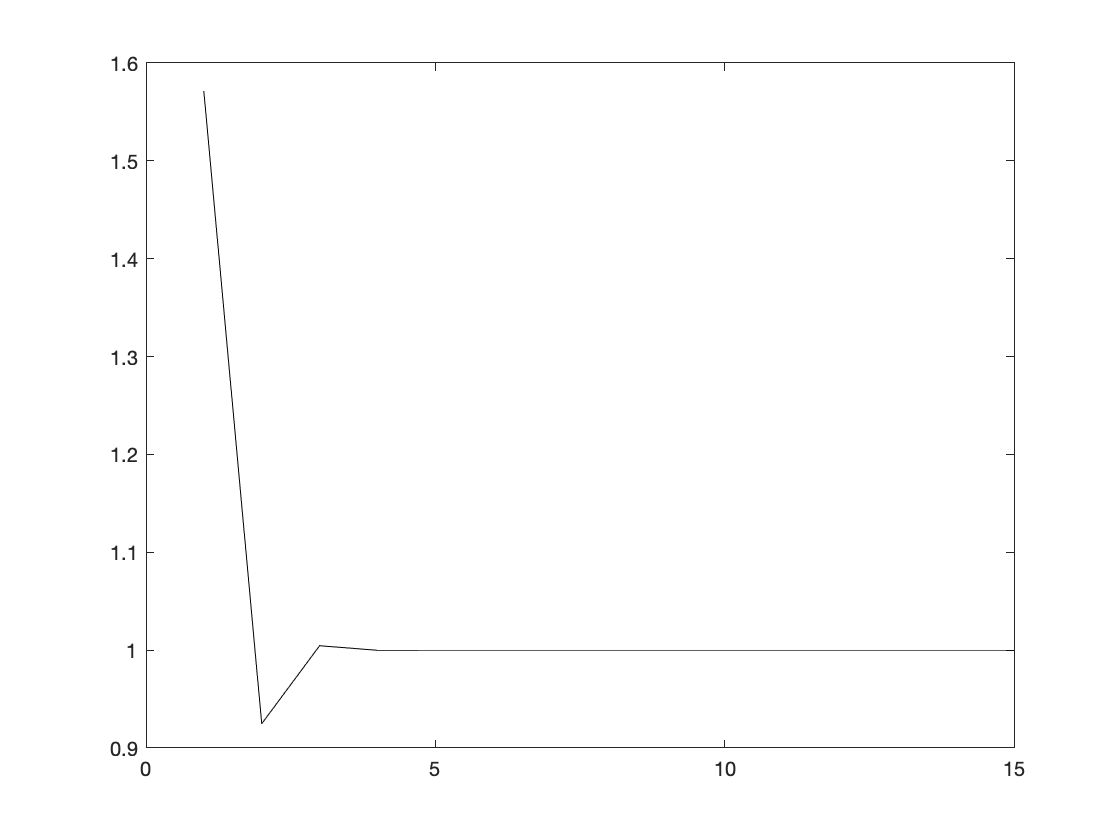

ans = 1.0000

sinSeries(pi/2,15)

**c) Using your function**, approximate $\sin \left(x\right)$ at $x=\frac{5\pi }{2}$ for `n = 1` to `15` terms. Produce a plot with the number of included terms on the x axis and the approximated value on the y axis. As the number of terms increase, the approximated value should converge to $\sin \left(\frac{5\pi }{2}\right)$

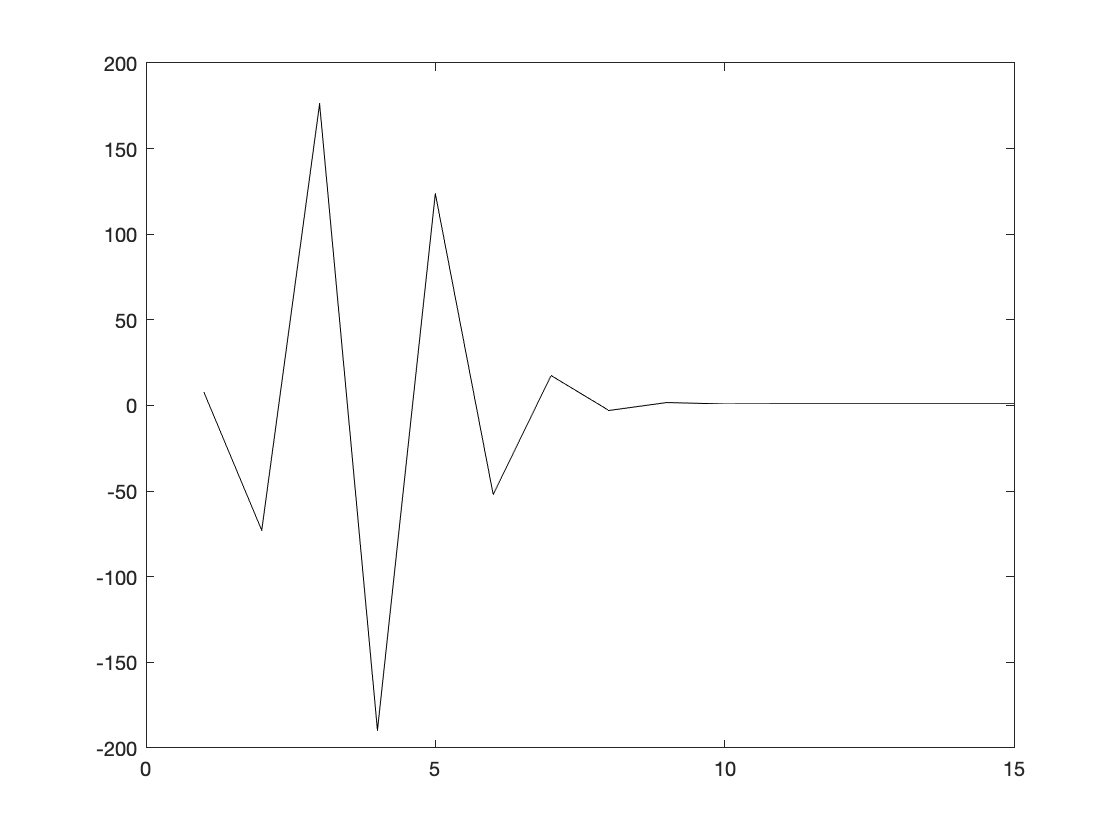

ans = 1.0000

sinSeries(5*pi/2,15)

**Note**: You should observe that more terms are required for the approximation to converge for x values "further from 0." This is because the MacLaurin series, by definition, is a *Taylor series expansion about **x = 0*. Simply put, this means that it will work for approximating `x` values further from zero, but more terms must be included in the computation. 

## PROBLEM 4 (15 pts): Equivalent resistance

As engineer, you may design circuits for signal processing, sensing, systems control, and other hardware applications. One of the simplest circuits is one containing multiple resistors arranged either in series or in parallel. A circuit diagram for each case is shown below.

        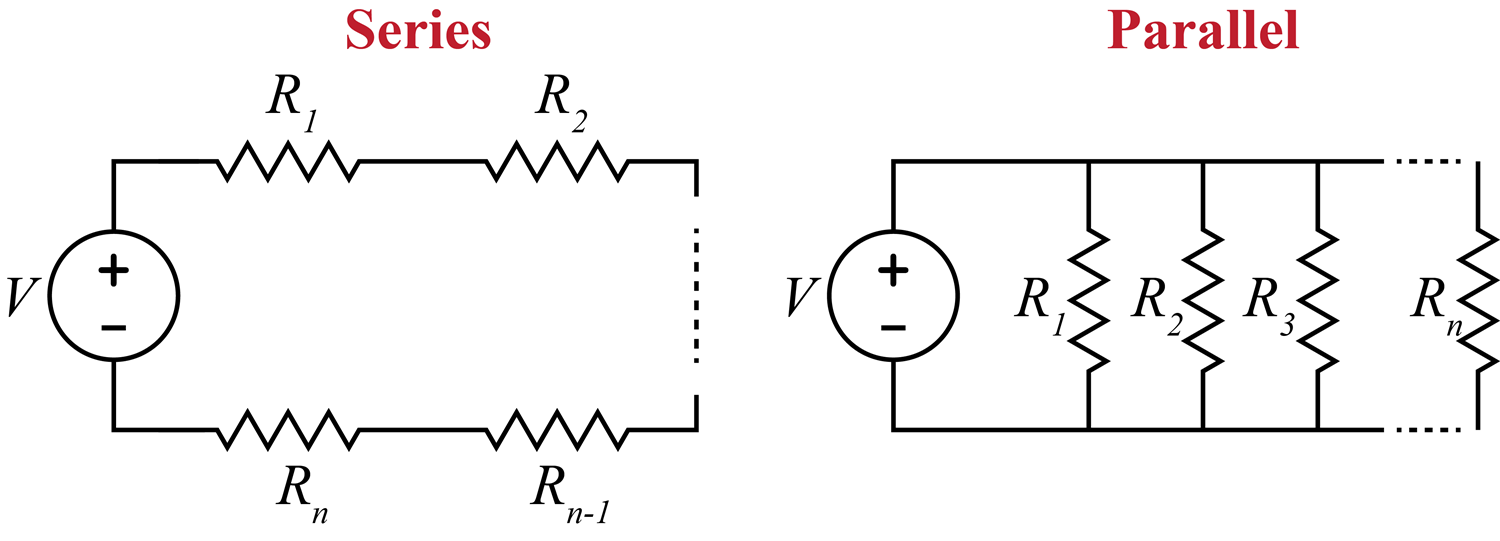

The equivalent resistance ($R_{\textrm{eq},s}$) for a circuit in which all $n$ resistors are present in **series** is given by the following equation.

        
$$R_{\textrm{eq},s} =\sum_{i=1}^n R_i$$


On the other hand, the equivalent resitance ($R_{\textrm{eq},p}$) for a circuit in which all $n$ resistors are present in **parallel** is given by the following equation.

        
$$R_{\textrm{eq},p} ={\left(\sum_{i=1}^n \frac{1}{R_i }\right)}^{-1}$$


In these equations, $R_i$ represents in the resistance of the $i$-th resistor in the circuit in a circuit containing $n$ resistors. 

**a)** **Design a function** (in the space provided at the end of this document) to calculate the equivalent resistance of a circuit for *either* a circuit with resistors arranged in series or in parallel. Your function should have the following characteristics:

- It should have the name `equivRes` and be contained in the space provided in this liveScript document.

- It should take **two inputs**: a vector in which **each entry is the resistance of one resistor in the circuit**, and a scalar to indicate whether the **series (**`1`**)** or **parallel (**`0`**)** calculation should be performed. If the **scalar input** is any number other than a `0` or `1`, the function should return `0`.

- It should be able to calculate the equivalent resistance for an input vector of **any** length.

- It should produce **one output**: a scalar representing the equivalent resistance of that circuit, or `0` (see above). 

**b)** Using your function, calculate the equivalent resistance of a circuit in which the resistors, given in the following vector, are arranged in series. Display the value of the equivalent resistance at the end of your script.

R_b = ones(1,10);
resistance(R_b, 1)

ans = 10

**c)** Using your function, calculate the equivalent resistance of a circuit in which the resistors, given in the following vector, are arranged in parallel. Display the value of the equivalent resistance at the end of your script.

R_c = [1:10,1:10,1:10,1:10];
resistance(R_c, 0)

ans = 0.0854

## PROBLEM 5 (25 pts): Infinite series, pt. 2

In **Problem 3** of this problem set, you evaluated how well the series approximation for $\sin \left(x\right)$ performed when evaluated at different $x$ values, for different numbers of terms included in the approximation. In this problem, we will take this a step further by investigating and comparing the computational efficiency of approximating $\cosh \left(x\right)$, the hyperbolic cosine function, using **(1) **`for`** loops** and **(2) vectorization** -- for any number of $n$ computed terms.

The hyperbolic cosine function, $\cosh \left(x\right)$ may be represented by the following infinite series representation, which to the limit of infinite terms ($n\longrightarrow \infty$) will exactly match the value of $\cosh \left(x\right)$. 

            
$$\cosh \left(x\right)=\sum_{k=0}^{\infty } \frac{1}{\left(2k\right)!}x^{2k} =1+\frac{x^2 }{2!}+\frac{x^4 }{4!}+\ldotp \ldotp \ldotp$$


In this case,

- `n=1` should approximate $\cosh \left(x\right)$ as $1$

- `n=2` should approximate $\cosh \left(x\right)$ as $1+\frac{x^2 }{2!}$

- `n=3 `should approximate $\cosh \left(x\right)$ as $1+\frac{x^2 }{2!}$+$\frac{x^4 }{4!}$

- (and so on)

**a) Create a function **called `cosh_for` in the space provided at the end of this Livescript document. This function should evaluate the series approximation to $\cosh \left(x\right)$ by using `for`** loops**. The function should take **two input scalars**, `x` and `n`, where `x` specifies the `x` value to calculate the approximation and `n` specifies the number of terms to include in the approximation. The function should **output two scalars**, `t` and `val`, where `t` specifies the computational time required to calculate the approximation and `val` is the corresponding `n`-term approximation for $\cosh \left(x\right)$, evaluated at `x`.

**b) Create a function** called `cosh_vec` in the space provided at the end of this Livescript document. This function should evaluate the series approximation to $\cosh \left(x\right)$ by using **vectorization**. This function should **not** contain any `for` loops. As above, the function should take **two input scalars**, `x` and `n`, where `x` specifies the `x` value to calculate the approximation and `n` specifies the number of terms to include in the approximation. The function should also **output two scalars**, `t` and `val`, where `t` specifies the computational time required to calculate the approximation and `val` is the corresponding `n`-term approximation for $\cosh \left(x\right)$, evaluated at `x`.

**Hint**: `sum()` may be useful in this problem.

**c)** Create a script that approximates cosh(x) at x = 1 using both `cosh_for() `and `cosh_vec()` for 1 ≤ n ≤ 5000 by increments of n=1. **Plot the computation time as a function of n**. Your plot should include a linear x-axis, a logarithmic y-axis, axis titles, and a legend. Your plot should be clear and look professional.

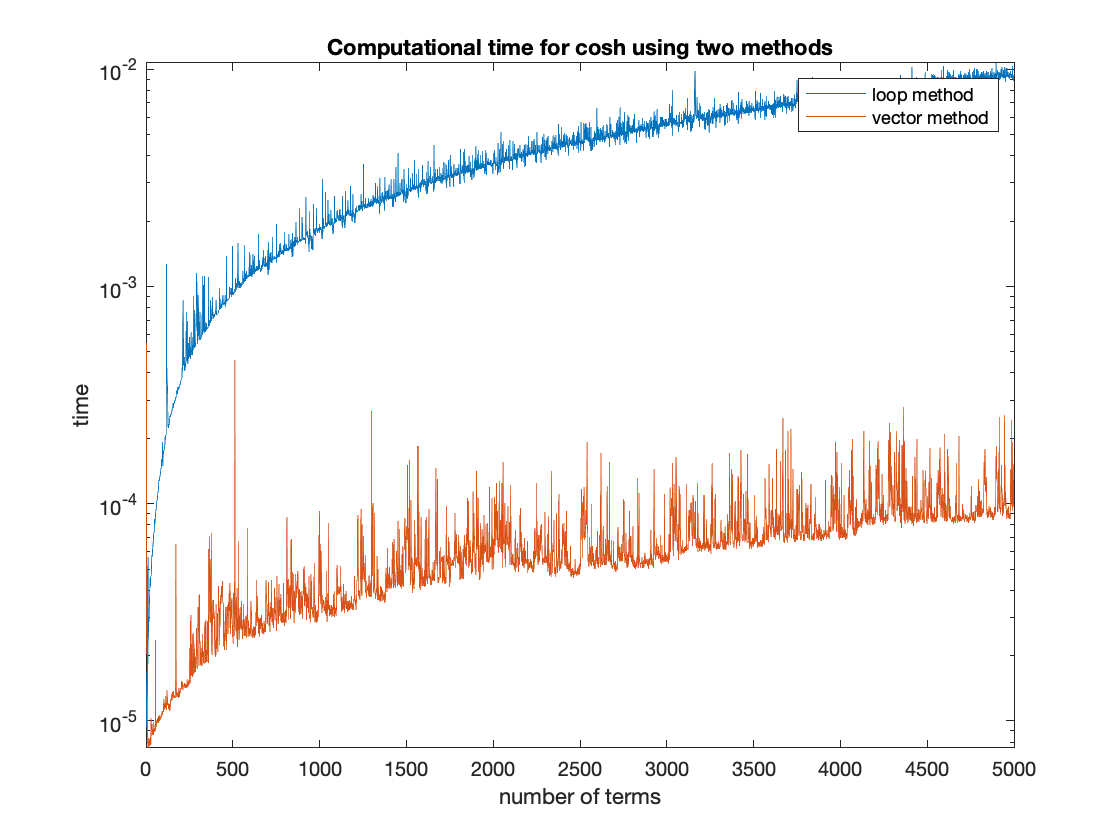

[val, t] = cosh_for(1, 10)

[val, t] = cosh_vec(1,10)
%preallocate an empty vector that holds the time.
time_for = zeros(1,5000);
%declare k in order to use it later on in graphinh
 
for k = 1:5000
    [time_for(k), ~] = cosh_for(1,k);
end

%repeats the other for loop but for teh vectorization
for k = 1:5000
    [time_vec(k), ~] = cosh_vec(1,k);
end

k = 1:5000; 
%hold on;
semilogy(k,time_for,k,time_vec)
xlabel('number of terms')
ylabel('time')
title('Computational time for cosh using two methods')
legend('loop method', 'vector method')

**Hint**: consult our lecture notes for useful tips on plotting.

**d) **Using one of the functions you created above, determine how many terms are necessary to approximate the value of $\cosh \left(\pi \right)$ to within 0.1% of its true value? Display this value at the end of your script.

%percentTrue = [~,time_vec]
%use a while loop to check when cosh is within the .1% of the value
%have a counter in order to see how many terms you go through
n = 1;
while i>0
    %grabs the value of cosh pi from the function 
    [~, cosh_vec_n] = cosh_vec(pi,n)
    %calculates the error as a percentage
    error = (abs(cosh(pi) - cosh_vec_n)/cosh(pi)) * 100   
    if error > 0.1 
        %adds to the original counter
        n = n+1;
    else 
        break 
    end
end

cosh_vec_n = 1

error = 91.3733

cosh_vec_n = 5.9348

error = 48.8024

cosh_vec_n = 9.9935

error = 13.7892

cosh_vec_n = 11.3288

error = 2.2703

cosh_vec_n = 11.5641

error = 0.2402

cosh_vec_n = 11.5899

error = 0.0176

disp(n)

     6



**Hint**: `cosh()` calls the hyperbolic cosine function in MATLAB.

## Problems Set 4: functions stored below

**Use the space below for PROBLEM 3.**

% n = ammount of tems 
% x = x value where u calculate the approximation 
%function should output the approximation of sin
%

function output = sinSeries(x,n)
    sum = 0;
    x_value = 1:n;
    y = [];
    for k = 1:n
        sum = sum + ((-1)^(k-1)) * (x.^(2*k-1))./(factorial(2*k-1)); 
        y(end+1) = sum;
    end
    output = sum;
    plot(x_value,y,'k-')
    xlabel("Amount of terms")
    ylabel("Value ")
end






**Use the space below for PROBLEM 4.**

function total_resistance = resistance(resistors, type) 
total_resistance = 0;
    %check which type the resistors are
    if type == 1
        %iterates through the length of the vector containing the resistors
        for k = 1:length(resistors)
            %adds the resistance in each indice to the total resistance
            %vector.
            total_resistance = total_resistance + resistors(k);
        end
    %iterates through to find the resistance of a parallel circuit
    elseif type == 0
        for n = 1:length(resistors)
            total_resistance = total_resistance + (1/resistors(n));
        end
        total_resistance = (total_resistance^-1);
    else 
        total_reisistance = 0;
    end
end






**Use the space below for PROBLEM 5, a).**

%function should output computational time and the approximation 
%input should be the amount of terms and the value 
function [t, val] = cosh_for(x, n)
    tic;
    output = 0;
    %runs through the amount of terms and keeps adds them to the
    %output variable
    for k = 1:n
        
        output = output + x^(2*(k-1))/(factorial(2*(k-1)));
    end
    val = output;
    t = toc;
    
end






**Use the space below for PROBLEM 5, b).**

%want to find the approximation of the cosh using vectors 
% find a wat yo make each value in the vector equal to that nomber in it's
% place
% the indeces should keep increasing their exponent by 1, and the factorial
% number by 1 
function [t,val] = cosh_vec(x,n)
    tic;
    % make a vector that goes from 1-n
    count = 1:n; 
    % have to use element wise in order to match the indices of the vectors
    % to each other 
    coshVector = x.^(2.*(count-1))./(factorial(2.*(count-1)));
    %adds up all of the terms in the vector. 
    val = sum(coshVector);
    t = toc;
end




